clear all; close all
A = [ 4 14 -12;
    0 -4 0;
    1.5 -1 -5];
B = [4; 0; 2];
J = [-1 1.2 3.4;
    -0.25 0.9 0.5;
    -0.85 0.8 2.4];
M = [0; 1; 1];
C = [0 1 0];

C = [C; C; C] %making square matrix out of C 

C =      0     1     0
     0     1     0
     0     1     0




%LMI variables
Pvar = sdpvar(3,3); %Lyapunov matrix
Zvar = sdpvar(3,3); %defining new indepenten matrices
Qvar = sdpvar(3,3);

ii = 100;           % maximal number of iteration steps
jj = 10; %max rough bisection steps

high = 100;
low = 1e-3;
Flow_stable = false

Flow_stable = logical
   0


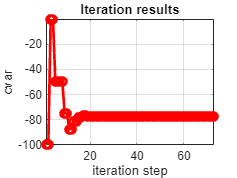

%setting bounds based on expected stability of the solution
if Flow_stable %we have a minimal dwell time d < 0, c > 0
    % Loop parameters cvar
    lb_cvar = low;             % initial value lower search bound
    ub_cvar = high;            % initial value upper search bound
    
    % Loop parameters dvar
    lb_dvar = -high;             % initial value lower search bound
    ub_dvar= -low;            % initial value upper search bound
else %we have a maximal dwell time d > 0, c < 0
    lb_cvar = -high;             % initial value lower search bound
    ub_cvar = -low;            % initial value upper search bound
    
    % Loop parameters dvar
    lb_dvar = low;             % initial value lower search bound
    ub_dvar= high;            % initial value upper search bound
end

%checking bounds
if lb_cvar > ub_cvar %lower bound 
    display('bounds are ill defined')
    
elseif lb_dvar > ub_dvar
    display('bounds are ill defined')
end
%
d_cvar = 1e-8;      % maximal difference in cvar between to different iteration steps
d_dvar = 1e-8;      % maximal difference in dvar between to different iteration steps

% Set initial loop values
lbf_cvar = NaN;      % lower bound feasible? NaN: not determined yet, 0: no, 1: yes
ubf_cvar = NaN;      % upper bound feasible? NaN: not determined yet, 0: no, 1: yes

% Set initial loop values
lbf_dvar = NaN;      % lower bound feasible? NaN: not determined yet, 0: no, 1: yes
ubf_dvar = NaN;      % upper bound feasible? NaN: not determined yet, 0: no, 1: yes

%tracking variables
cvar_track = [];
dvar_track = [];

for i = 1:ii
    %Computing cvar and dvar using bisection
    cvar = bisection(lb_cvar,ub_cvar,lbf_cvar,ubf_cvar);
    dvar = bisection(lb_dvar,ub_dvar,lbf_dvar,ubf_dvar);

    [Pvar,Qvar,Zvar, L,diagnostics] = LMI_q2f(A,J,cvar,dvar,Pvar,Qvar,Zvar);

    % Check result
    % pres : Primal constraint residuals
    % dres : Dual constraint residuals
    [pres,~] = check(L);

    %checking feasiblity and changing bounds cvar or dvar  
    if mod(i,2) == 0
        [ub_cvar, lb_cvar, lbf_cvar, ubf_cvar] = CheckFeasibility(cvar,ub_cvar,lb_cvar,lbf_cvar,ubf_cvar,pres,diagnostics);
    else
        [ub_dvar, lb_dvar, lbf_dvar, ubf_dvar] = CheckFeasibility(dvar,ub_dvar,lb_dvar,lbf_dvar,ubf_dvar,pres,diagnostics);
    end


    
    %storing iteration
    cvar_track(i) = cvar;
    dvar_track(i) = dvar;

    if i>=4
         %check has minus two because the variable is changed every other cycle
        if abs(cvar-cvar_track(i-2)) < d_cvar
            if abs(dvar-dvar_track(i-2)) < d_dvar
                break;              % break loop if accurate enough
            end
        end
    end

    % Store feasible solution
    if min(pres) > 0 && diagnostics.problem == 0
        feasible.Pvar = Pvar;
        feasible.Qvar = Qvar;
        feasible.Zvar = Zvar;
        feasible.cvar = cvar;
        feasible.dvar = dvar;
    end

end

% Plot iteration history
figure(1)
tiledlayout(1,2)
plot(cvar_track,'ro-','LineWidth',2)
xlabel('iteration step')
ylabel('cvar')
title('Iteration results')
grid on
axis tight

nexttile

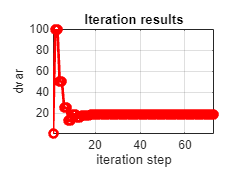

plot(dvar_track,'ro-','LineWidth',2)
xlabel('iteration step')
ylabel('dvar')
title('Iteration results')
grid on
axis tight


% Retrieve output
P = value(feasible.Pvar)

P =     1.5435   -0.2462   -2.4277
   -0.2462    4.7345   -0.3159
   -2.4277   -0.3159    4.2826


Q =    NaN   NaN   NaN
   NaN   NaN   NaN
   NaN   NaN   NaN


Z =    NaN   NaN   NaN
   NaN   NaN   NaN
   NaN   NaN   NaN


L1 =    NaN   NaN   NaN
   NaN   NaN   NaN
   NaN   NaN   NaN


L2 =    NaN   NaN   NaN
   NaN   NaN   NaN
   NaN   NaN   NaN



c = value(feasible.cvar)

c = -77.4463

d = value(feasible.dvar)

d = 18.2426



dwelltime = abs(d)/abs(c)

dwelltime = 0.2356